## Open the project

To open asbQuadcopter.prj, run the following code (in Command Window to prevent livescript output):

openProject('C:\Users\david\OneDrive\Documents\Part 15 - Winter 2023\EECS 499\Technical work\asbQuadcopterRealFlight (version 6)');

## Simulate

scenarios = {'Hover'; 'LandingSearch'; 'ConstantAltitude'; 'ConstantAltitudeAndThenLinearX'; 'ConstantAltitudeAndThenLinearY'; ...
             'ConstantAltitudeAndThenLinearYaw'; 'ConstantAltitudeThenLinearYawThenLinearY'; 'RectangularLoop'};
TFinals = [10; 15; 30; 40; 40; 40; 40; 128];
in = Simulink.SimulationInput.empty(size(scenarios, 1), 0);
for i = 1 : size(scenarios, 1)
    in(i) = Simulink.SimulationInput('asbQuadcopter');
    in(i) = in(i).setBlockParameter(['flightControlSystem/Flight Control System/'...
            'landing logic/Position//Attitude Reference'], ...
            'ActiveScenario', scenarios{i});
    in(i) = in(i).setVariable('TFinal', TFinals(i), 'Workspace', 'asbQuadcopter');
end

out = sim(in(8)); % simulate with the "RectangularLoop" scenario for 128 seconds
% out = sim(in); % alternatively, simulate all the scenarios in one fell swoop

## Analyze the simulation data

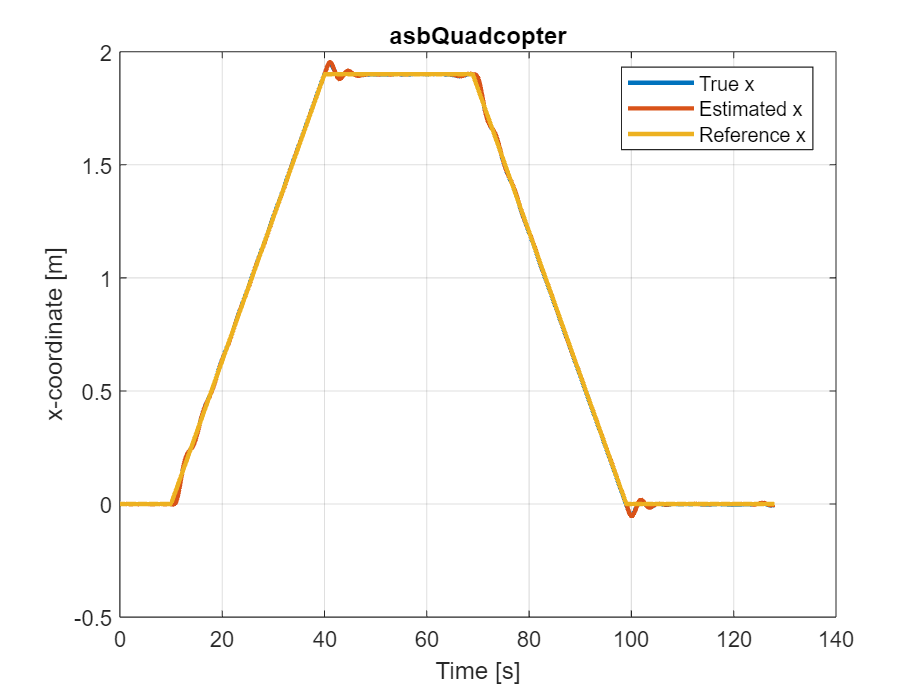

t = out.posref.time; % basically equivalent to t = (0 : Ts : TFinal)';
xyzrpy = out.xyzrpy;
estim = out.estim.signals.values;
posref = out.posref.signals.values;
motor = out.motor.signals.values;
sensor = out.sensor.signals.values;

plot(t, xyzrpy(:, 1) - xyzrpy(1, 1) * ones(size(t)), t, estim(:, 1), t, posref(:, 1), ...
     'LineWidth', 2);
legend('True x', 'Estimated x', 'Reference x', 'Location', 'best');
xlabel('Time [s]');
ylabel('x-coordinate [m]');
title('asbQuadcopter');
grid on;

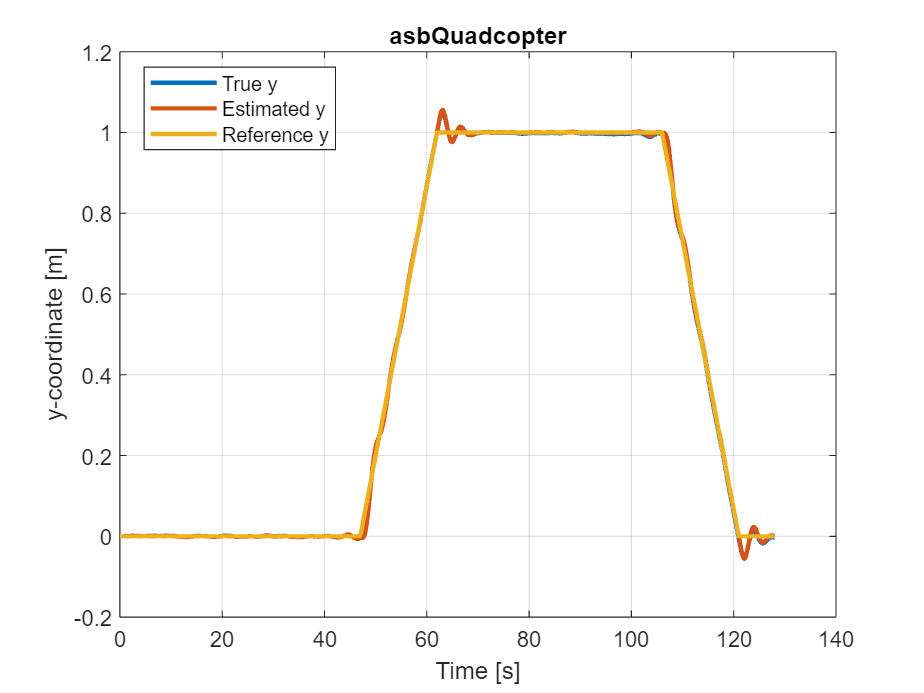


plot(t, xyzrpy(:, 2) - xyzrpy(1, 2) * ones(size(t)), t, estim(:, 2), t, posref(:, 2), ...
     'LineWidth', 2);
legend('True y', 'Estimated y', 'Reference y', 'Location', 'best');
xlabel('Time [s]');
ylabel('y-coordinate [m]');
title('asbQuadcopter');
grid on;

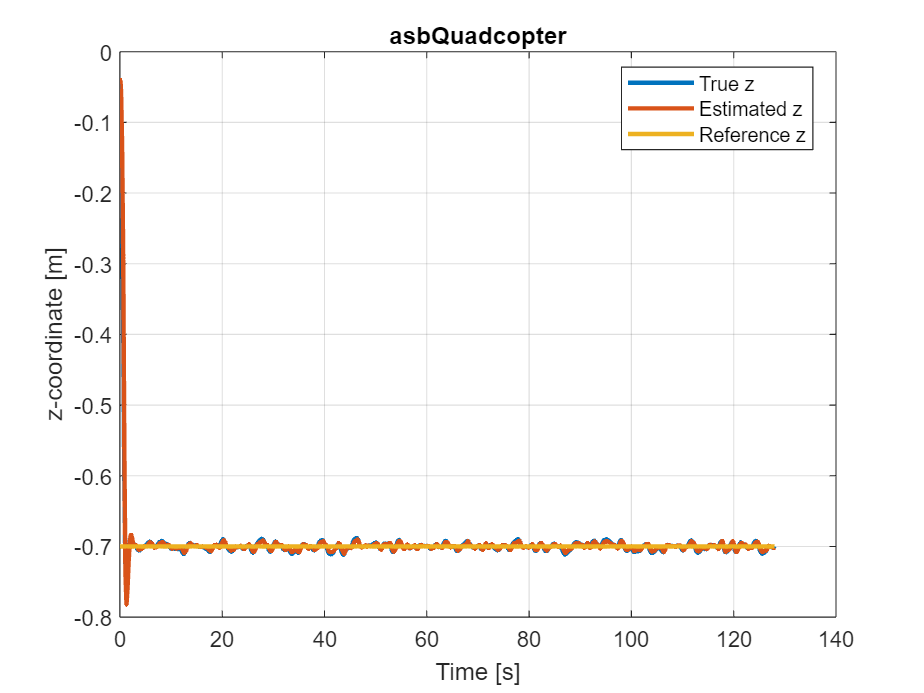


plot(t, xyzrpy(:, 3), t, estim(:, 3), t, posref(:, 3), 'LineWidth', 2);
legend('True z', 'Estimated z', 'Reference z', 'Location', 'best');
xlabel('Time [s]');
ylabel('z-coordinate [m]');
title('asbQuadcopter');
grid on;

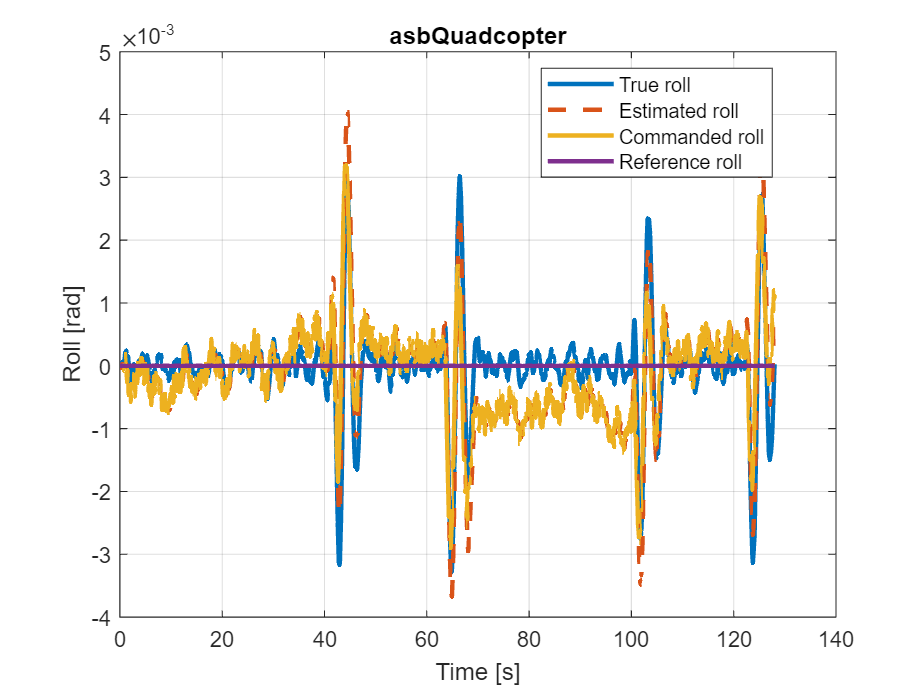


plot(t, xyzrpy(:, 4), t, estim(:, 6), '--', t, posref(:, 8), t, posref(:, 6), 'LineWidth', 2);
legend('True roll', 'Estimated roll', 'Commanded roll', 'Reference roll', ...
       'Location', 'best');
% plot(t, xyzrpy(:, 4), t, estim(:, 6), t, posref(:, 6), 'LineWidth', 2);
% legend('True roll', 'Estimated roll', 'Reference roll', ...
%        'Location', 'best');
xlabel('Time [s]');
ylabel('Roll [rad]');
title('asbQuadcopter');
grid on;

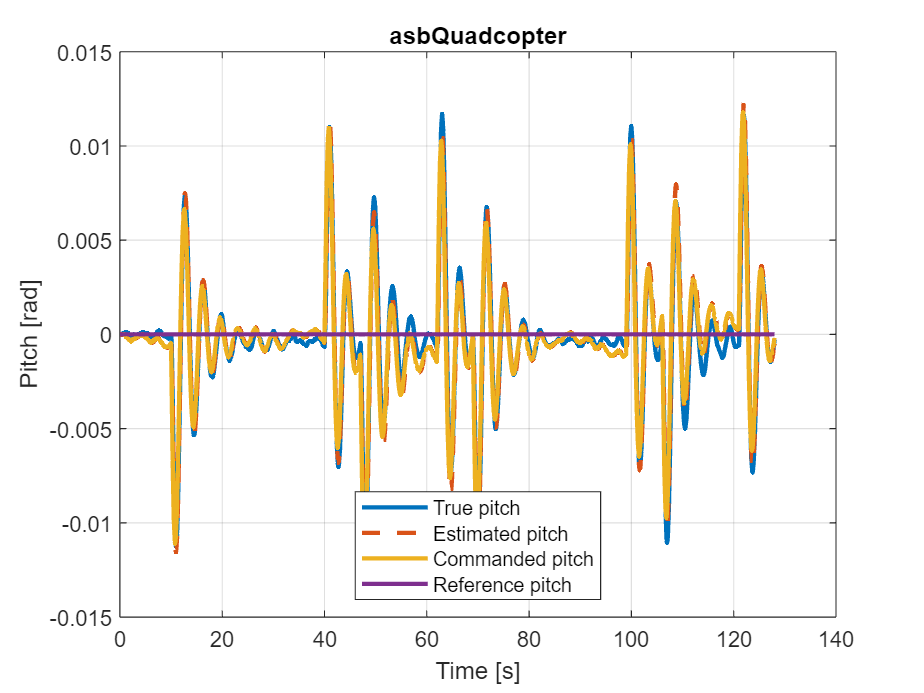


plot(t, xyzrpy(:, 5), t, estim(:, 5), '--', t, posref(:, 7), t, posref(:, 5), 'LineWidth', 2);
legend('True pitch', 'Estimated pitch', 'Commanded pitch', 'Reference pitch', ...
       'Location', 'south');
% plot(t, xyzrpy(:, 5), t, estim(:, 5), t, posref(:, 5), 'LineWidth', 2);
% legend('True pitch', 'Estimated pitch', 'Reference pitch', ...
%        'Location', 'east');
xlabel('Time [s]');
ylabel('Pitch [rad]');
title('asbQuadcopter');
grid on;

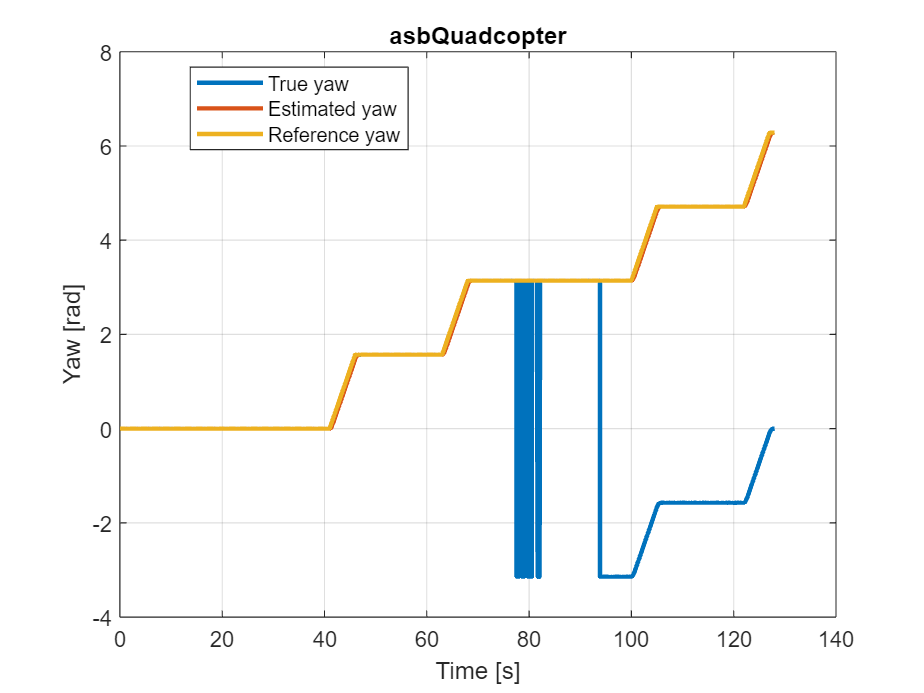


plot(t, xyzrpy(:, 6), t, estim(:, 4), t, posref(:, 4), 'LineWidth', 2);
legend('True yaw', 'Estimated yaw', 'Reference yaw', 'Location', 'best');
xlabel('Time [s]');
ylabel('Yaw [rad]');
title('asbQuadcopter');
grid on;

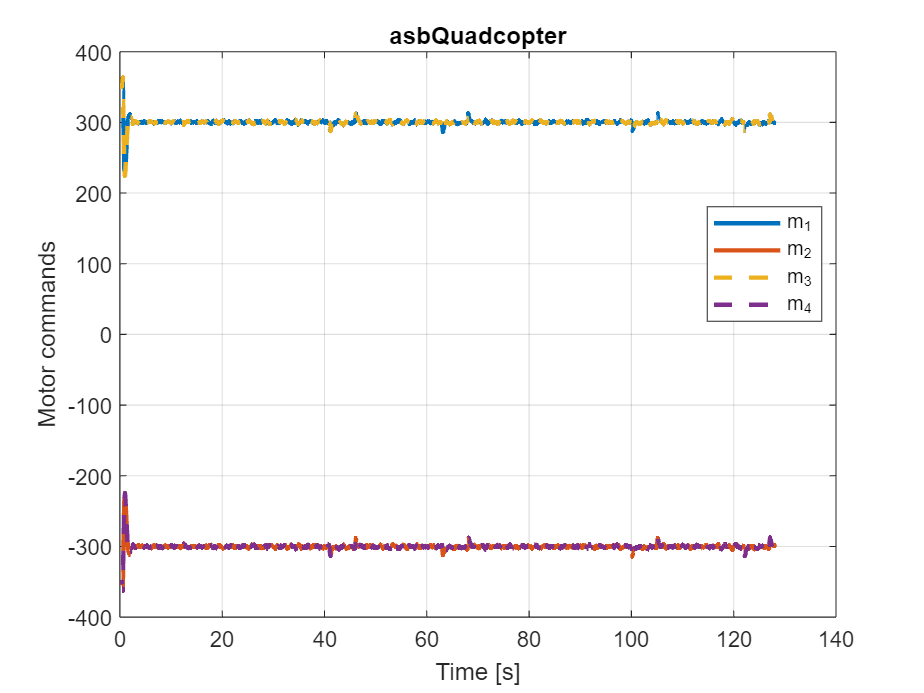


plot(t, motor(:, 1), t, motor(:, 2), t, motor(:, 3), '--', t, motor(:, 4), '--', ...
     'LineWidth', 2);
legend('m_1', 'm_2', 'm_3', 'm_4', 'Location', 'best');
xlabel('Time [s]');
ylabel('Motor commands');
title('asbQuadcopter');
grid on;

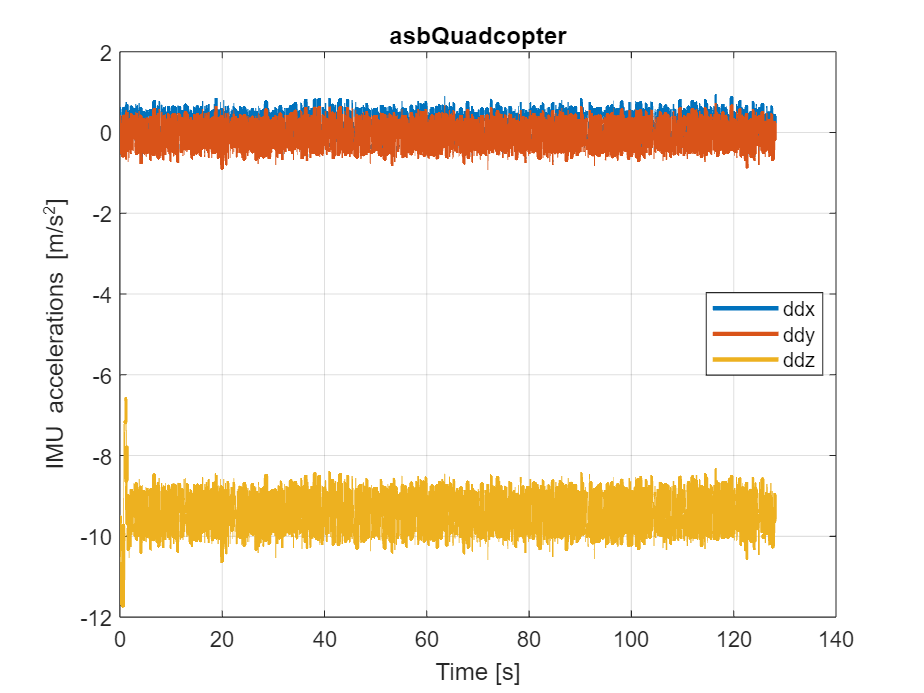


plot(t, sensor(:, 1), t, sensor(:, 2), t, sensor(:, 3), 'LineWidth', 2);
legend('ddx', 'ddy', 'ddz', 'Location', 'best');
xlabel('Time [s]');
ylabel('IMU accelerations [m/s^2]');
title('asbQuadcopter');
grid on;

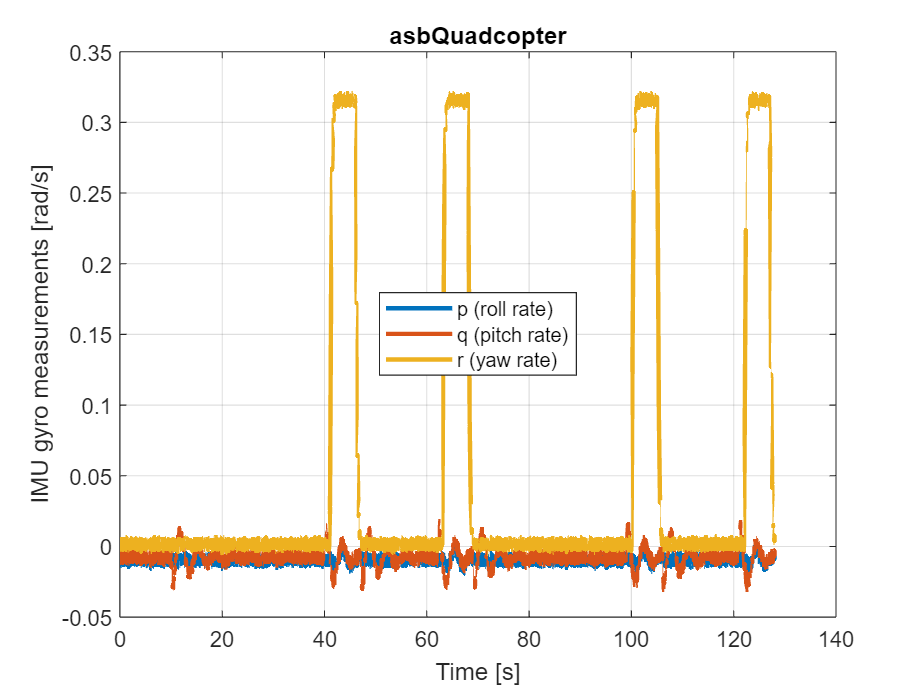


plot(t, sensor(:, 4), t, sensor(:, 5), t, sensor(:, 6), 'LineWidth', 2);
legend('p (roll rate)', 'q (pitch rate)', 'r (yaw rate)', 'Location', 'best');
xlabel('Time [s]');
ylabel('IMU gyro measurements [rad/s]');
title('asbQuadcopter');
grid on;

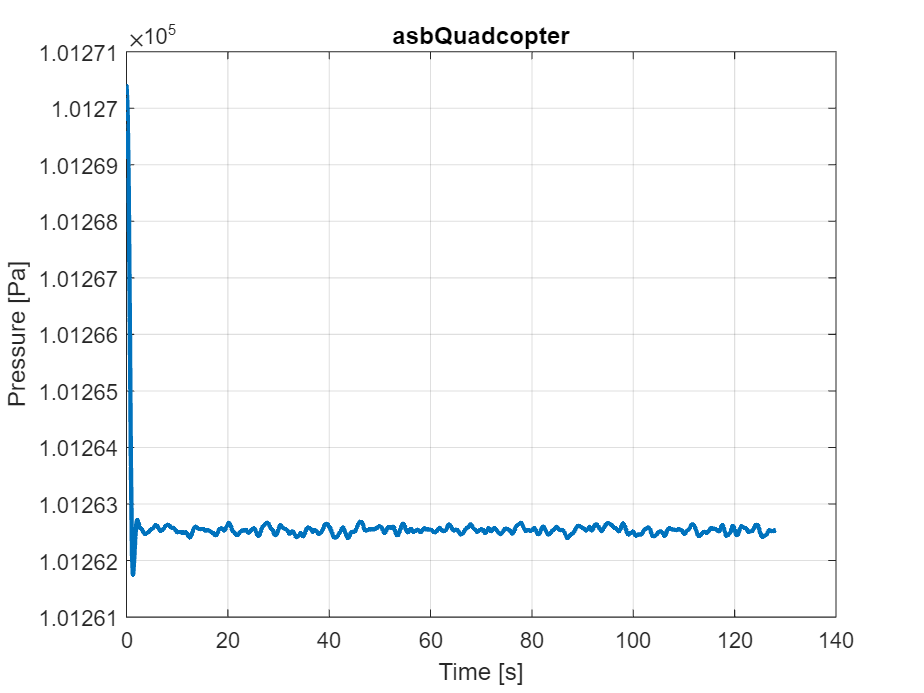


plot(t, sensor(:, 8), 'LineWidth', 2);
xlabel('Time [s]');
ylabel('Pressure [Pa]');
title('asbQuadcopter');
grid on;

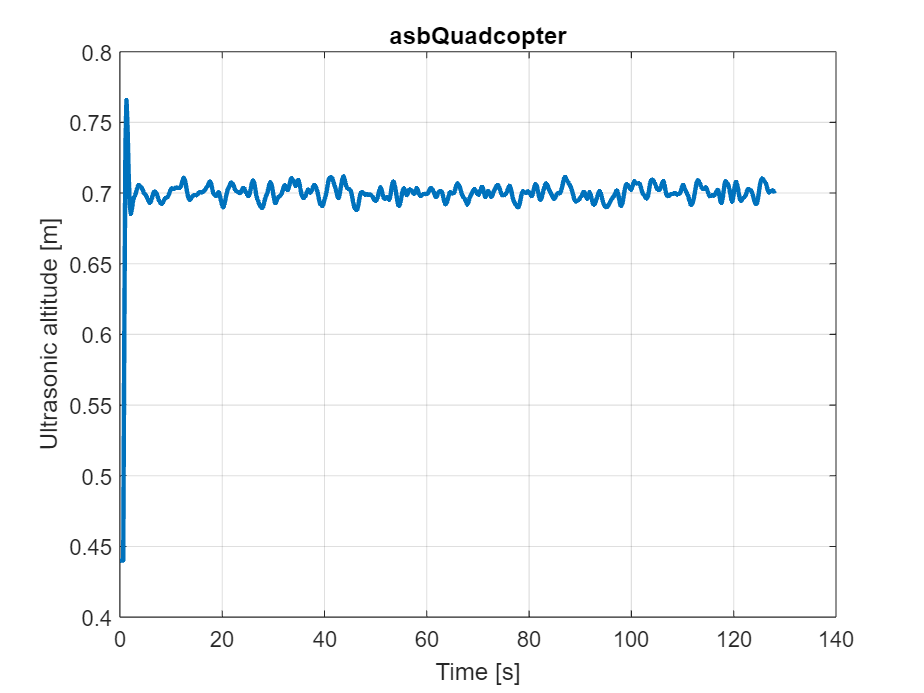


plot(t, sensor(:, 7), 'LineWidth', 2);
xlabel('Time [s]');
ylabel('Ultrasonic altitude [m]');
title('asbQuadcopter');
grid on;

## Analyze the real-flight data

whos('-file', 'RSdata.mat')

  Name               Size              Bytes  Class     Attributes

  rt_calib           1x1               11416  struct              
  rt_cmd             1x1             1127542  struct              
  rt_estim           1x1             1434742  struct              
  rt_motor           1x1              615540  struct              
  rt_optical         1x1             1025142  struct              
  rt_posref          1x1             1025142  struct              
  rt_sensor          1x1             1229942  struct              
  rt_tout         1000x1                8000  double              
  rt_yout            1x1               26566  struct              



load('RSdata.mat');

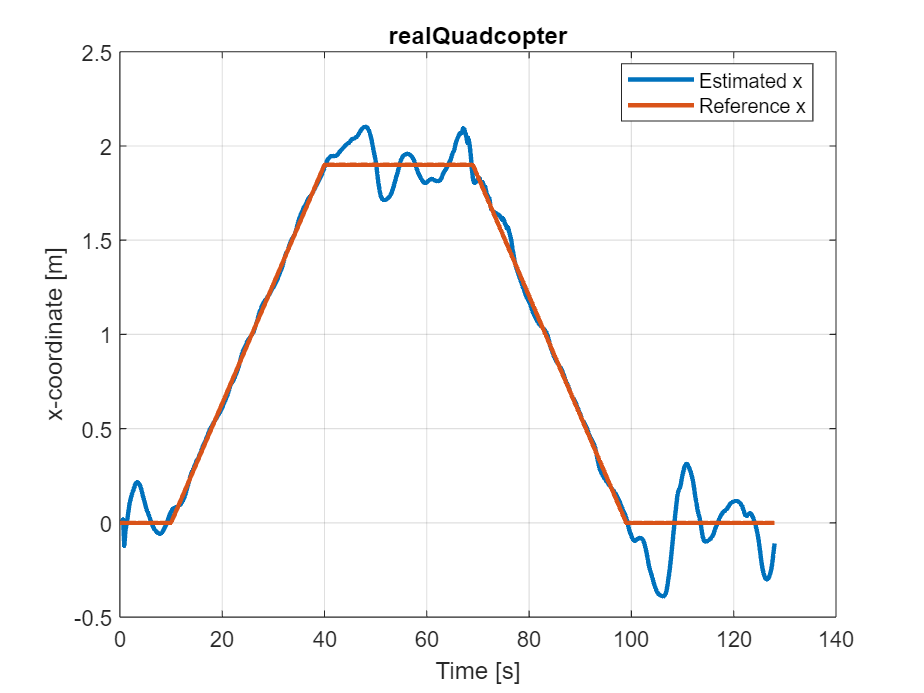

t_real = rt_posref.time(1 : end, :);
posref_real = rt_posref.signals.values(1 : end, :);
estim_real = rt_estim.signals.values(1 : end, :);
motor_real = rt_motor.signals.values(1 : end, :);
sensor_real = rt_sensor.signals.values(1 : end, :);

plot(t_real, estim_real(:, 1), t_real, posref_real(:, 1), 'LineWidth', 2);
legend('Estimated x', 'Reference x', 'Location', 'best');
xlabel('Time [s]');
ylabel('x-coordinate [m]');
title('realQuadcopter');
grid on;

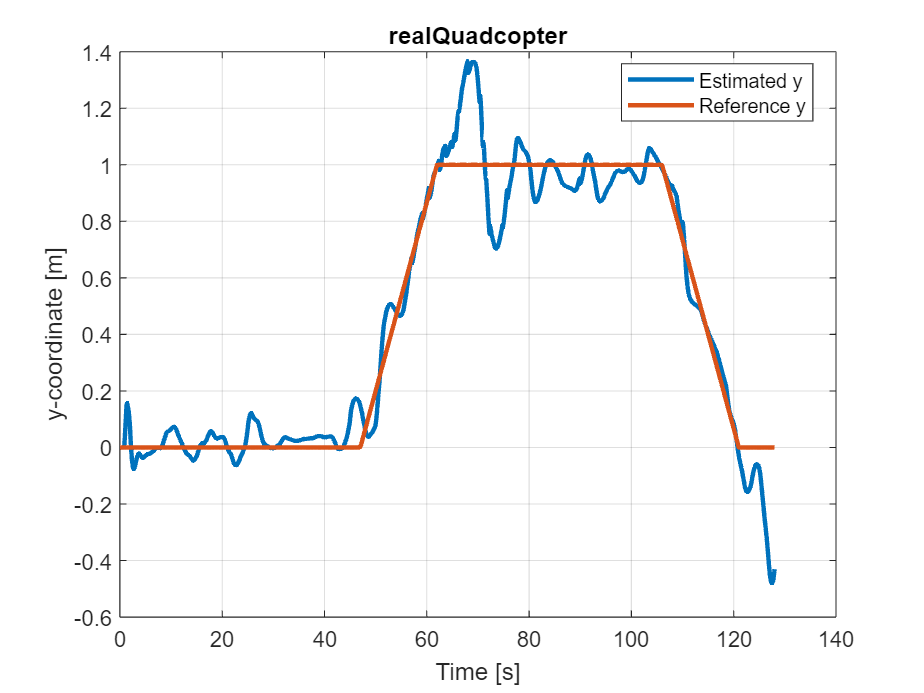


plot(t_real, estim_real(:, 2), t_real, posref_real(:, 2), 'LineWidth', 2);
legend('Estimated y', 'Reference y', 'Location', 'best');
xlabel('Time [s]');
ylabel('y-coordinate [m]');
title('realQuadcopter');
grid on;

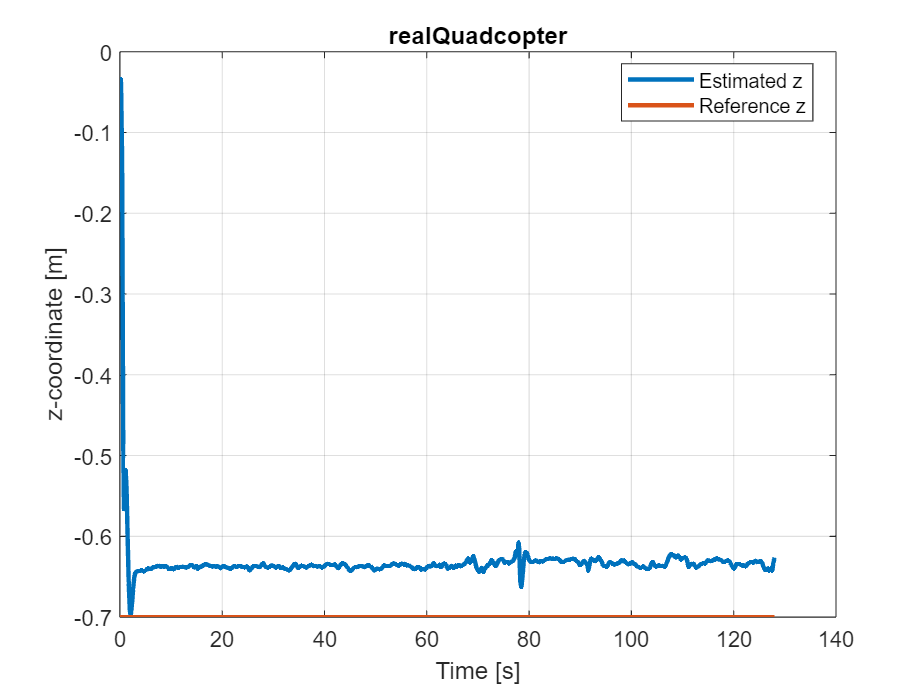


plot(t_real, estim_real(:, 3), t_real, posref_real(:, 3), 'LineWidth', 2);
legend('Estimated z', 'Reference z', 'Location', 'best');
xlabel('Time [s]');
ylabel('z-coordinate [m]');
title('realQuadcopter');
grid on;

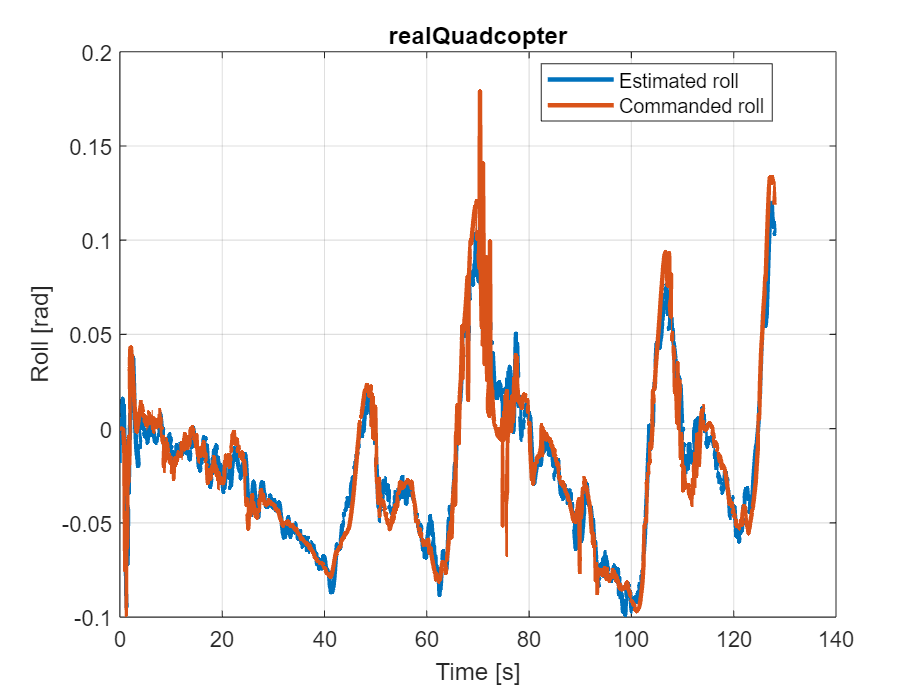


plot(t_real, estim_real(:, 6), t_real, posref_real(:, 8), 'LineWidth', 2);
legend('Estimated roll', 'Commanded roll', 'Location', 'best');
xlabel('Time [s]');
ylabel('Roll [rad]');
title('realQuadcopter');
grid on;

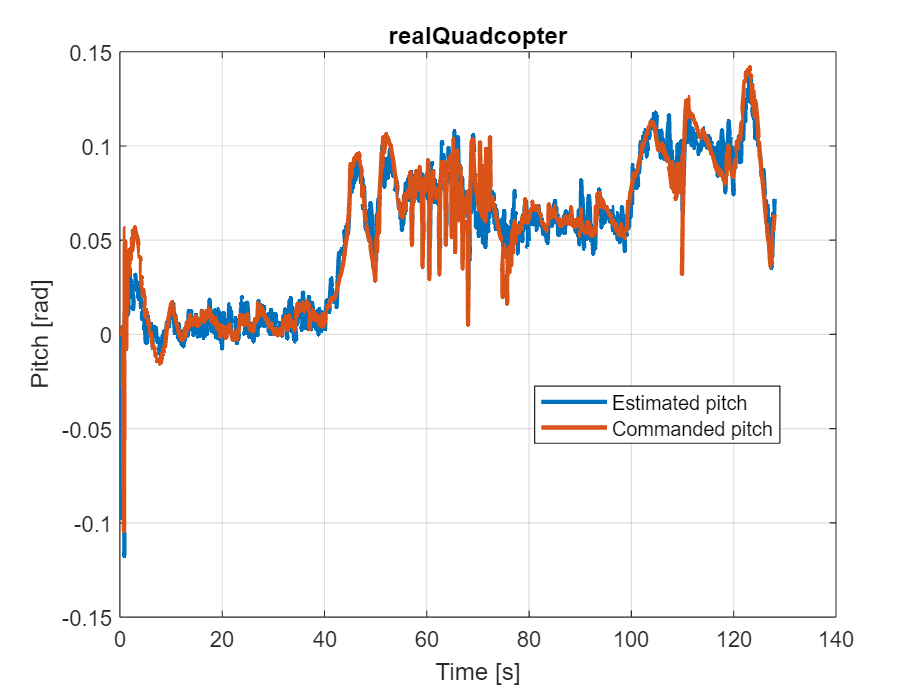


plot(t_real, estim_real(:, 5), t_real, posref_real(:, 7), 'LineWidth', 2);
legend('Estimated pitch', 'Commanded pitch', 'Location', 'best');
xlabel('Time [s]');
ylabel('Pitch [rad]');
title('realQuadcopter');
grid on;

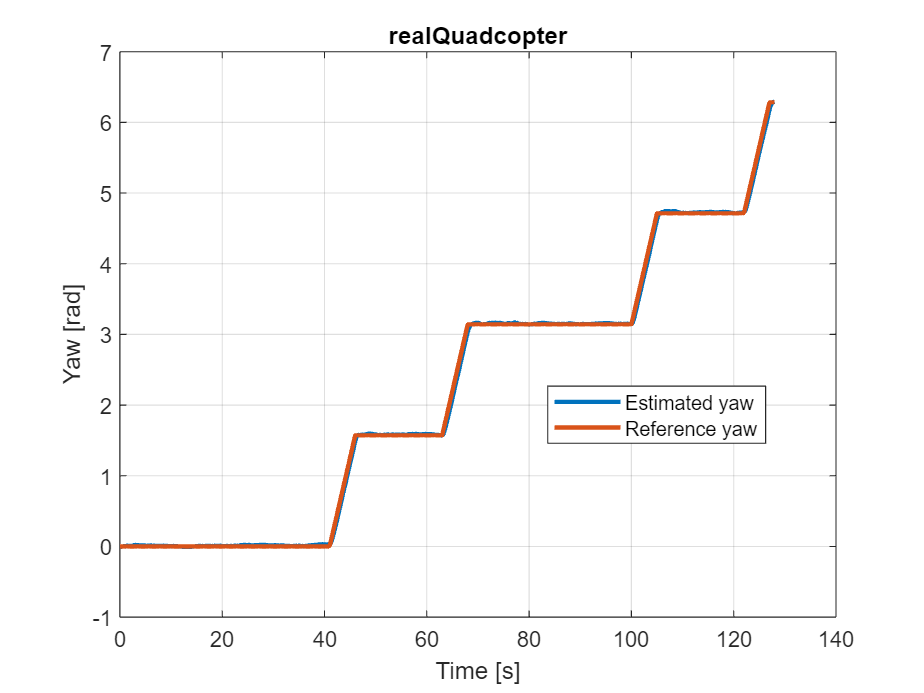


plot(t_real, estim_real(:, 4), t_real, posref_real(:, 4), 'LineWidth', 2);
legend('Estimated yaw', 'Reference yaw', 'Location', 'best');
xlabel('Time [s]');
ylabel('Yaw [rad]');
title('realQuadcopter');
grid on;

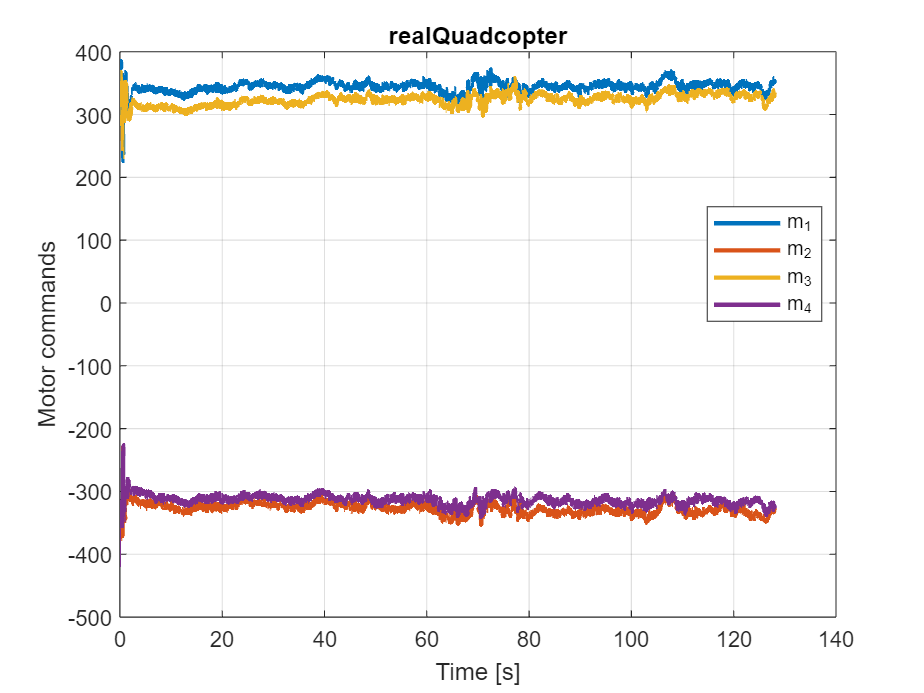


plot(t_real, motor_real(:, 1), t_real, motor_real(:, 2), t_real, motor_real(:, 3), ...
     t_real, motor_real(:, 4), 'LineWidth', 2);
legend('m_1', 'm_2', 'm_3', 'm_4', 'Location', 'best');
xlabel('Time [s]');
ylabel('Motor commands');
title('realQuadcopter');
grid on;

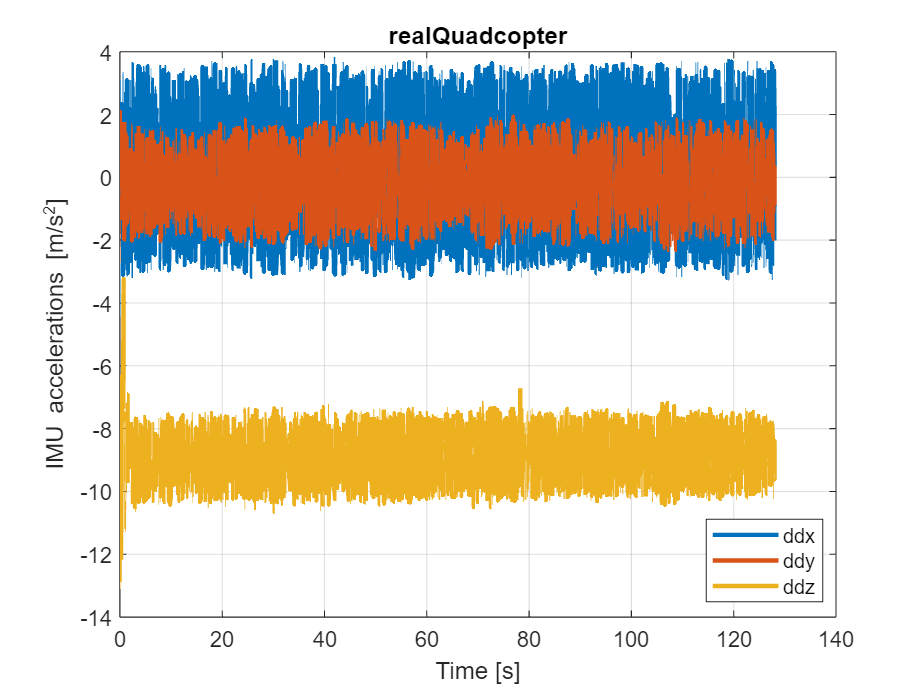


plot(t_real, sensor_real(:, 1), t_real, sensor_real(:, 2), t_real, sensor_real(:, 3), ...
     'LineWidth', 2);
legend('ddx', 'ddy', 'ddz', 'Location', 'best');
xlabel('Time [s]');
ylabel('IMU accelerations [m/s^2]');
title('realQuadcopter');
grid on;

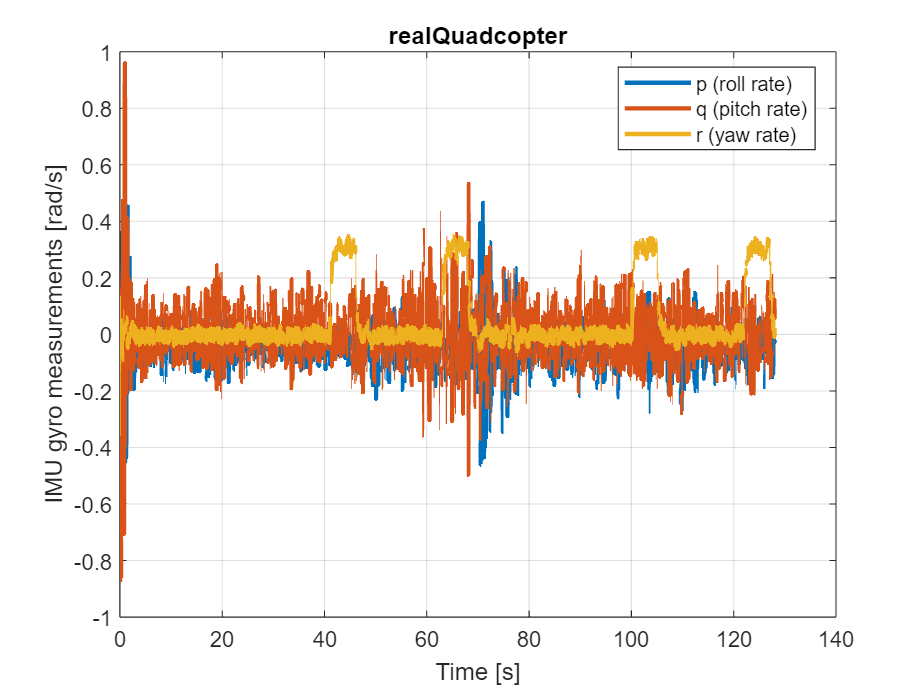


plot(t_real, sensor_real(:, 4), t_real, sensor_real(:, 5), t_real, sensor_real(:, 6), ...
     'LineWidth', 2);
legend('p (roll rate)', 'q (pitch rate)', 'r (yaw rate)', 'Location', 'best');
xlabel('Time [s]');
ylabel('IMU gyro measurements [rad/s]');
title('realQuadcopter');
grid on;

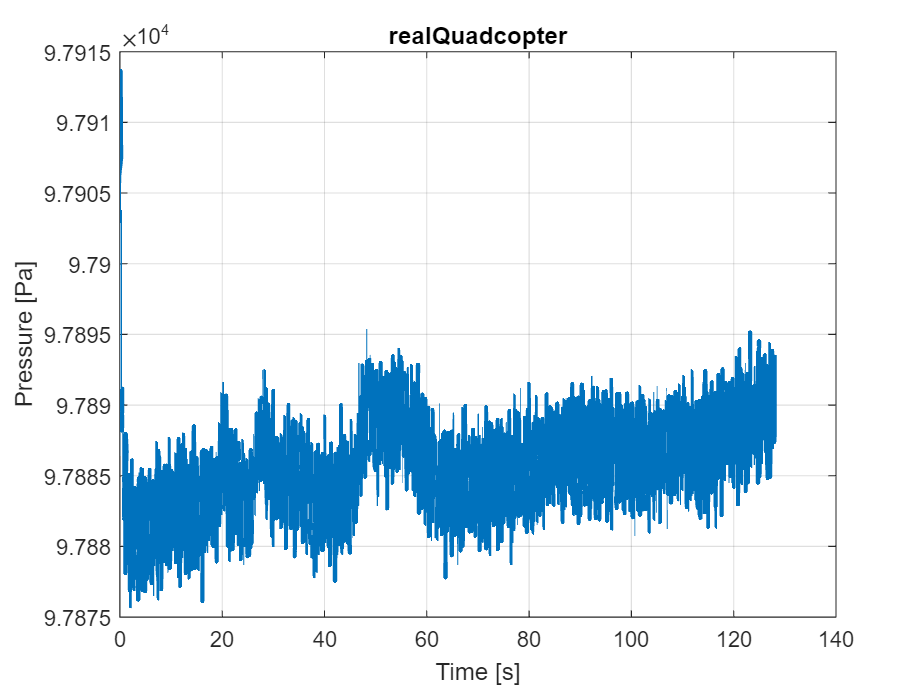


plot(t_real, sensor_real(:, 8), 'LineWidth', 2);
xlabel('Time [s]');
ylabel('Pressure [Pa]');
title('realQuadcopter');
grid on;

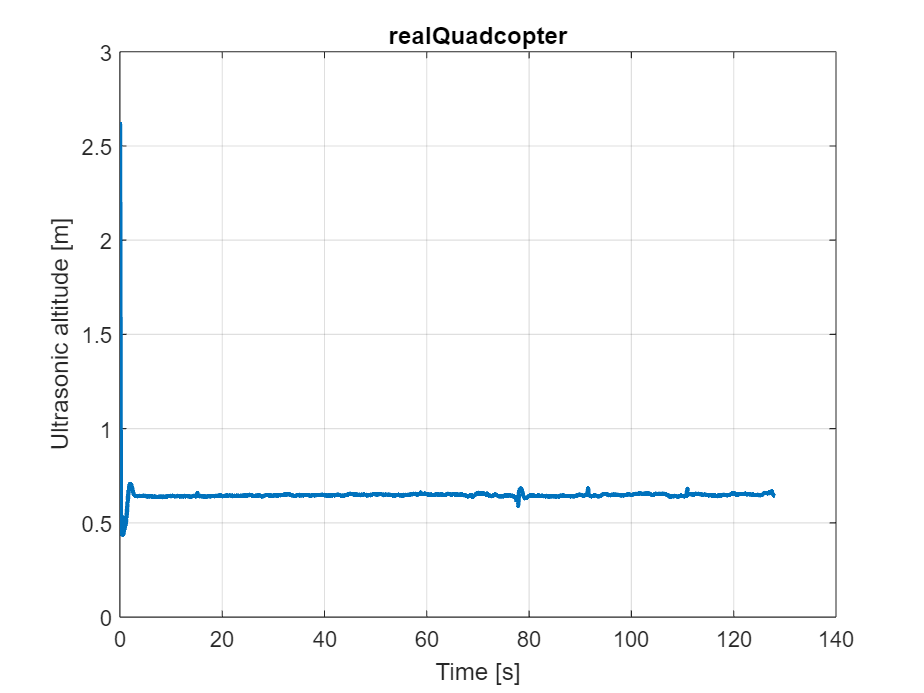


plot(t_real, sensor_real(:, 7), 'LineWidth', 2);
xlabel('Time [s]');
ylabel('Ultrasonic altitude [m]');
title('realQuadcopter');
grid on;

## Calibrate the mass

z_ref = -0.7;                                       % reference z
z_old = estim_real(end, 3)                          % previous steady-state z

z_old = single
-0.6264

m_old = Vehicle.Airframe.mass                       % previous mass

m_old = 0.0800

P_z = 0.8;                                          % proportional gain for altitude controller
m_new = ((z_ref - z_old) * P_z - g * m_old) / (-g)  % calibrated mass

m_new = single
0.0860

## Estimate the expected steady-state z with the calibrated mass

z_ref = -0.7;                                                                % reference z
z_old = -0.6264;                                                             % previous steady-state z
m_old = 0.08;                                                                % previous estimated mass
P_z = 0.8;                                                                   % proportional gain for altitude controller
m_new = 0.08;                                                                % calibrated mass
z_new_expected = z_ref - ((z_ref - z_old) * P_z - g * (m_old - m_new)) / P_z % expected new steady-state z

z_new_expected = -0.6264

## Compare the altitude performance in simulation and in real flight

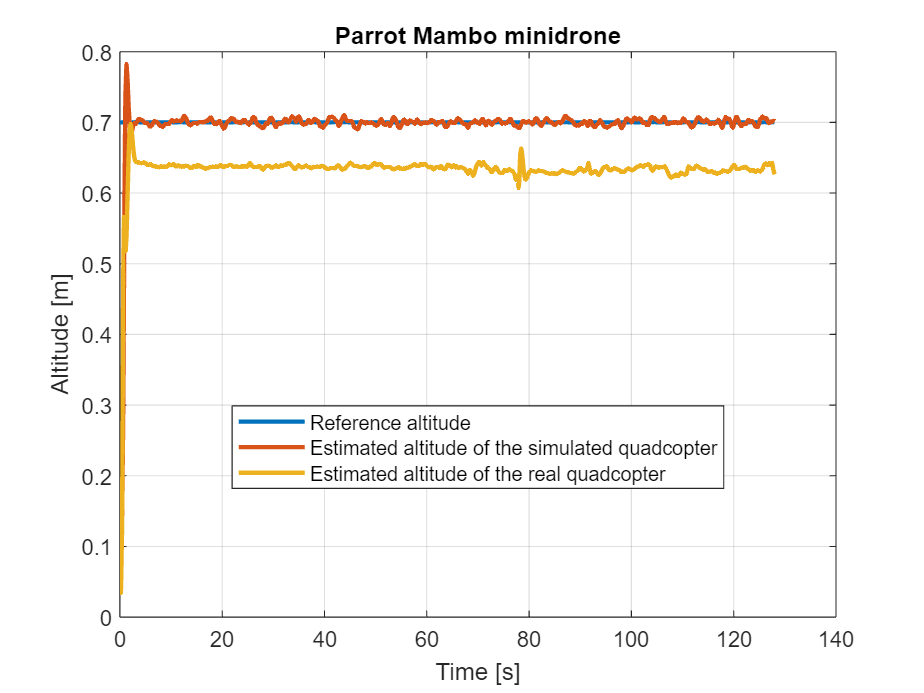

plot(t_real, -posref_real(:, 3), t, -estim(:, 3), t_real, -estim_real(:, 3), 'LineWidth', 2);
legend('Reference altitude', 'Estimated altitude of the simulated quadcopter', 'Estimated altitude of the real quadcopter', 'Location', 'best');
xlabel('Time [s]');
ylabel('Altitude [m]');
title('Parrot Mambo minidrone');
grid on;